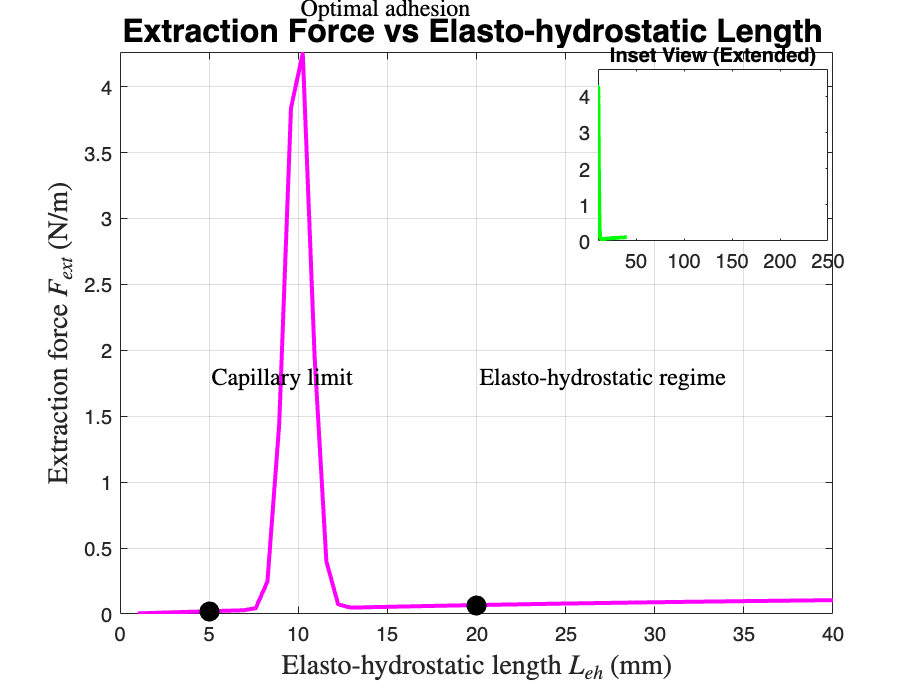

% Define constants
L_gc = 2.7; % Gravitational capillary length in mm
L_eh = linspace(1, 40 , 60); % Extended range of Elasto-hydrostatic length in mm
L_peak = 10; % Peak location for optimal adhesion (approximate)
a = 4.5; % Maximum force at the peak (increased for higher plot height)
b = 0.7; % Width of the peak

% Compute F_ext using a Gaussian-like model with adjustments
F_ext = a * exp(-((L_eh - L_peak).^2) / (2 * b^2)) + ...
        0.15 * (1 - exp(-0.03 * L_eh)); % Adding background force decay

% Plot the main graph
figure;
plot(L_eh, F_ext, 'm-', 'LineWidth', 2); hold on;

% Adding annotations for snapshots
snapshots_L = [5, 10, 20, 50];
snapshots_F = a * exp(-((snapshots_L - L_peak).^2) / (2 * b^2)) + ...
               0.15 * (1 - exp(-0.03 * snapshots_L));
scatter(snapshots_L, snapshots_F, 100, 'k', 'filled'); % Snapshot points

% Customize the plot
xlabel('Elasto-hydrostatic length $L_{eh}$ (mm)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Extraction force $F_{ext}$ (N/m)', 'Interpreter', 'latex', 'FontSize', 14);
title('Extraction Force vs Elasto-hydrostatic Length ', 'FontSize', 16);
grid on;

% Set axis limits for wider x-axis and scaled y-axis
xlim([0, 40]);
ylim([0, max(F_ext) + 0.01]); % Extra space above the peak

% Add text annotations
text(5, 1.8, 'Capillary limit', 'Interpreter', 'latex', 'FontSize', 12);
text(10, 4.6, 'Optimal adhesion', 'Interpreter', 'latex', 'FontSize', 12);
text(20, 1.8, 'Elasto-hydrostatic regime', 'Interpreter', 'latex', 'FontSize', 12);

% Add inset for extended L_eh range
axes('Position', [0.65, 0.65, 0.25, 0.25]);
plot(L_eh, F_ext, 'g-', 'LineWidth', 2);
xlim([10, 250]); % Extended range for the inset
ylim([0, max(F_ext) + 0.5]);
title('Inset View (Extended)', 'FontSize', 10);

% Save plot
saveas(gcf, 'Adjusted_Fig10_ExtractionForce.png');